# EMT for EPANET-MSX

### **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'net2-cl2.inp'; % you can also try 'net2-cl2.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)

Error using epanet
Error: File: epanet.m Line: 1 Column: 1
The input was too complicated or too big for MATLAB to parse.

G.plot

### **Multi-species chemical reactions**

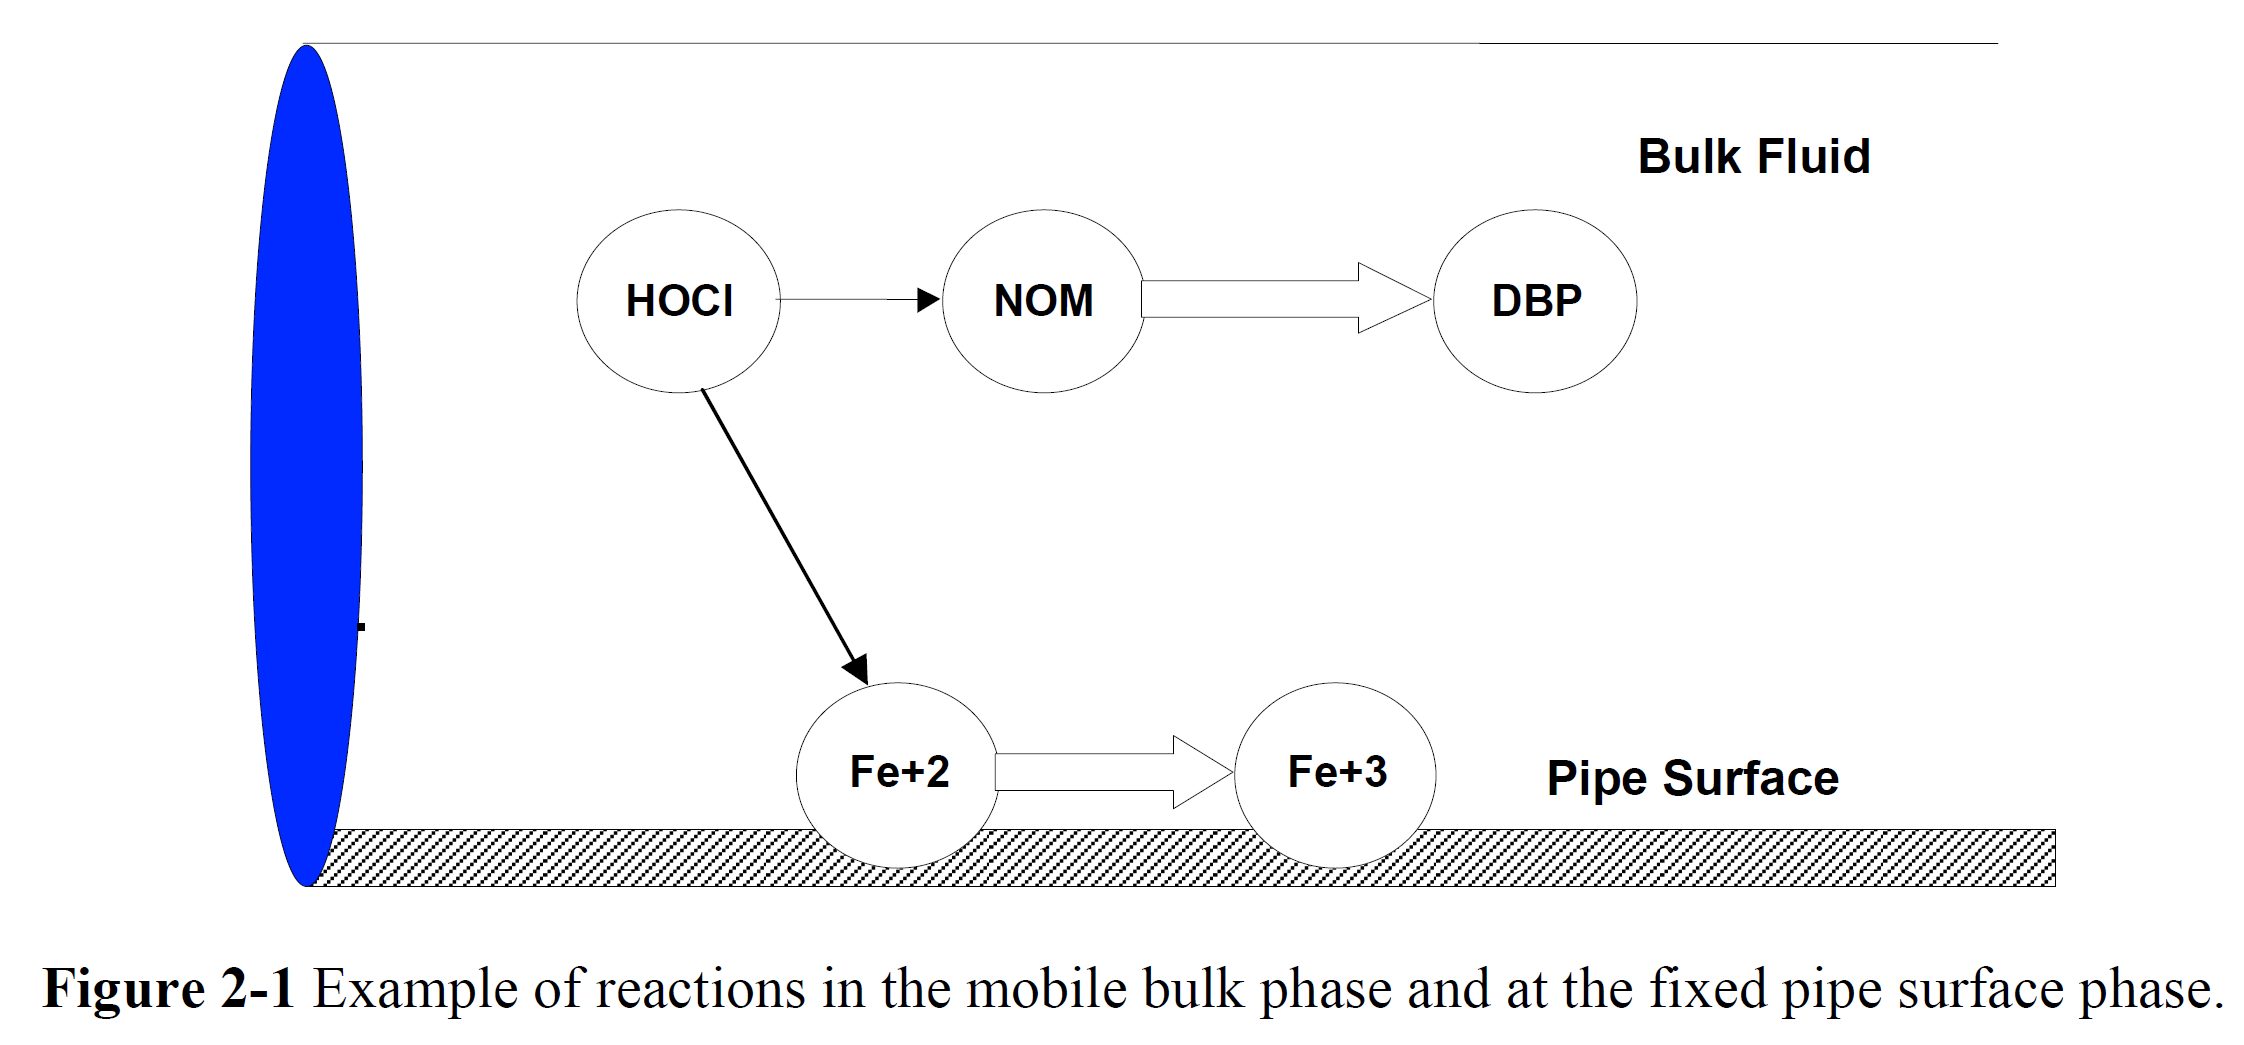

Reactions in water can be described using a set of Differential Algebraic Equations (DAE):


$$\frac{dx_b}{dt}=f(x_b,x_s,z_b,z_s)$$



$$\frac{dx_s}{dt}=g(x_b,x_s,z_b,z_s)$$



$$0=h(x_b,x_s,z_b,z_s)$$


These equations describe most of the reactions in water distribution systems. The solution methodology follows the following steps:

- Split the pipes into segments

- Solve the reaction equations for each segment

- Compute the advection (movement based on flows)

- Mix the bulk concentrations with the pipe wall concentrations 

- Recompute segmens

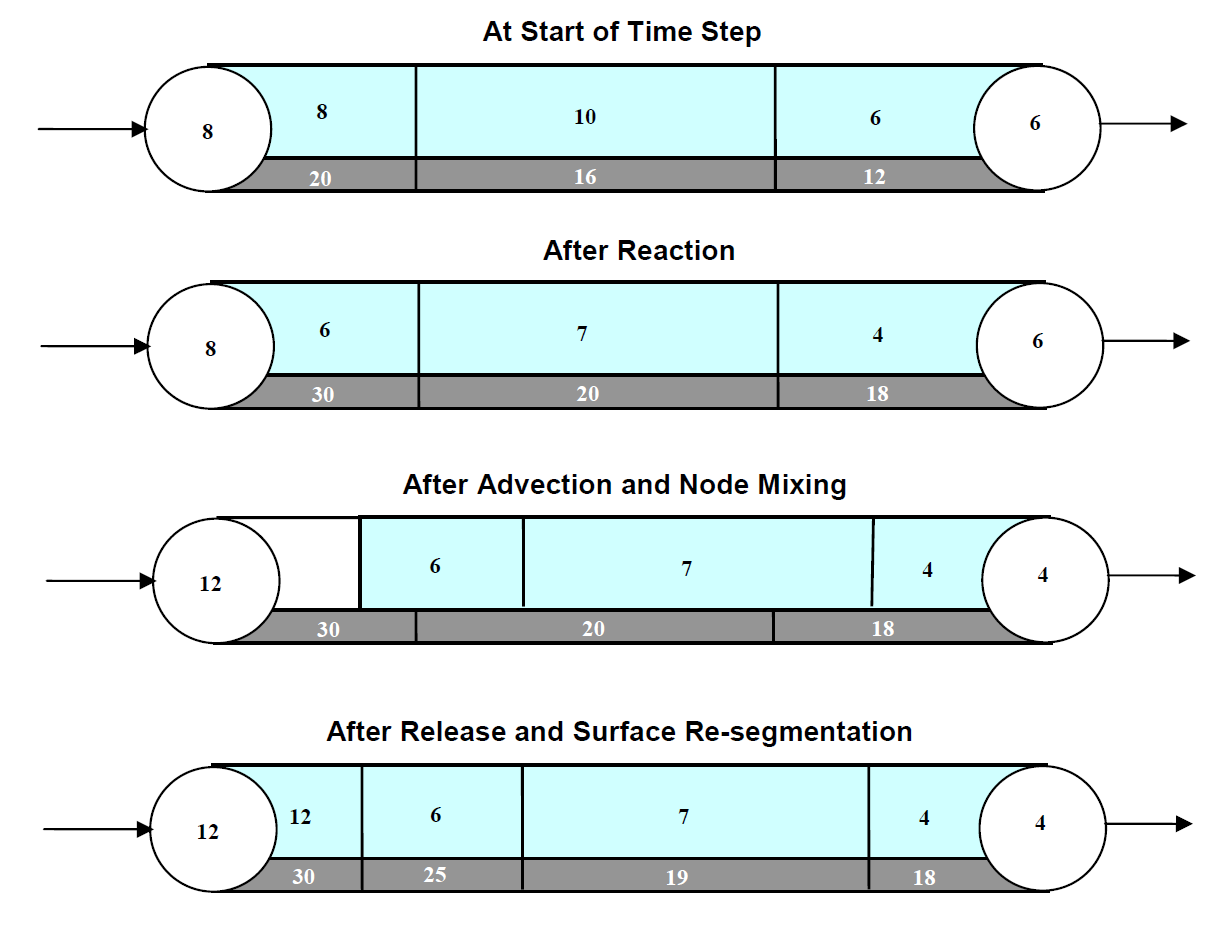

The set of diferential equations can be solved using an explicit method, e.g. **Runge-Kutta** or **Forward Euler** method.

** Chlorine reactions**

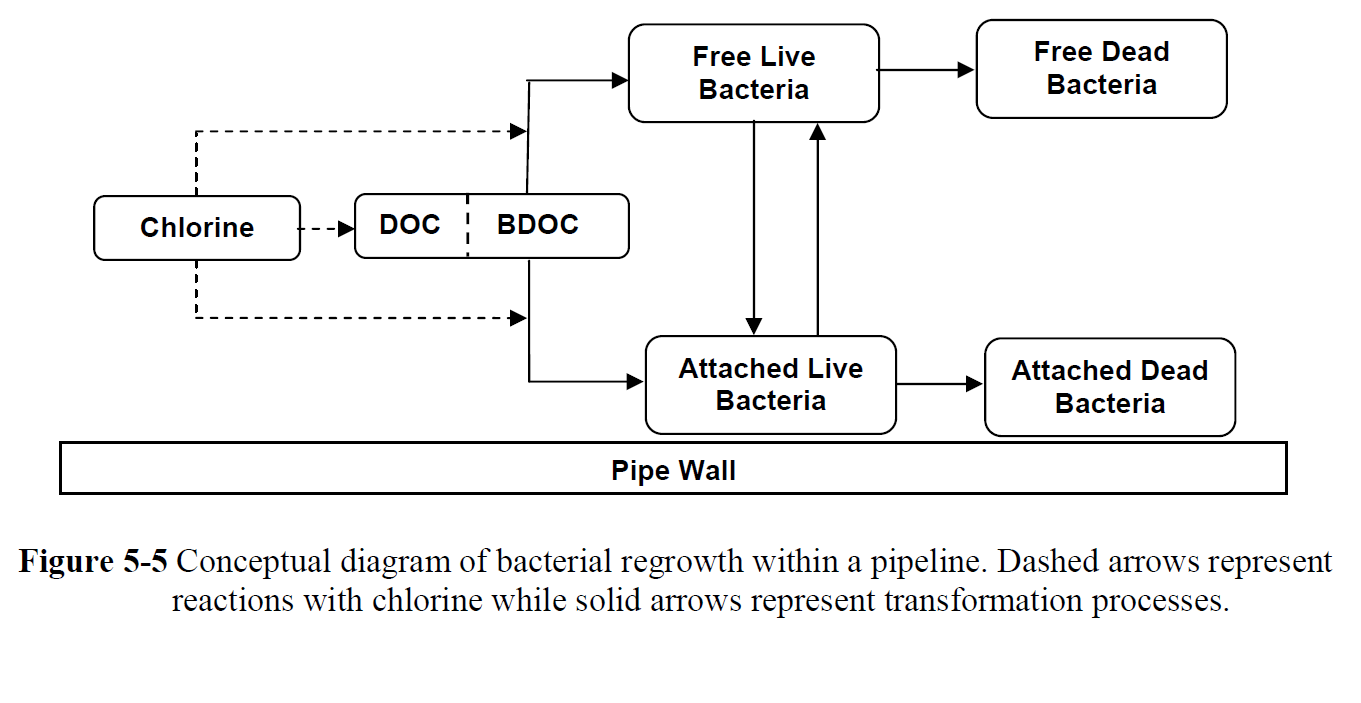

The most standard assumption is that Free Chlorine concentration is linear, i.e, 


$$\frac{dC(t)}{dt} = -k_bC(t)$$


Where $C(t)$ is the free chlorine concentration measured in $mg/L$.

% Example MSX file
fid = fopen('net2-cl2.msx','r')
c = fread(fid, inf, 'uint8=>char')'

**How to load an MSX file**

% Load EPANET-MSX file
G.loadMSXFile('net2-cl2.msx') % Load MSX file with reactions
qual_res_MSX = G.getMSXComputedQualitySpecie('CL2')
Q_msx = G.getMSXComputedQualityNode  % Compute water quality using MSX

Plot MSX species in MATLAB Figure

G.plotMSXSpeciesNodeConcentration(5,1)

**Another example**

% Get quality of specific nodes.
sensor_index = [2, 3, 5];
sensors_names = G.getNodeNameID(sensor_index)
QN = G.getMSXComputedQualityNode(sensor_index)

% Get quality of specific links.
QL = G.getMSXComputedQualityLink(sensor_index)

% Get species names.
type = G.getMSXSpeciesNameID;

% Get quality for specific species type (nodes and links).
MSX_comp = G.getMSXComputedQualitySpecie(type)

figure
G.plotMSXSpeciesNodeConcentration(3,1)

**Unload libraries**

G.unloadMSX;
G.unload;
